# Homogeneous Propagation Medium Example

clear
% create the computational grid
Nx = 128;           % number of grid points in the x (row) direction
Ny = 128;           % number of grid points in the y (column) direction
dx = 0.1e-3;        % grid point spacing in the x direction [m]
dy = 0.1e-3;        % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);
% define the properties of the propagation medium
medium.sound_speed = 1500;  % [m/s]
medium.alpha_coeff = 0.75;  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;
% create initial pressure distribution using makeDisc
disc_magnitude = 5; % [Pa]
disc_x_pos = 50;    % [grid points]
disc_y_pos = 50;    % [grid points]
disc_radius = 8;    % [grid points]
disc_1 = disc_magnitude * makeDisc(Nx, Ny, disc_x_pos, disc_y_pos, disc_radius);

disc_magnitude = 3; % [Pa]
disc_x_pos = 80;    % [grid points]
disc_y_pos = 60;    % [grid points]
disc_radius = 5;    % [grid points]
disc_2 = disc_magnitude * makeDisc(Nx, Ny, disc_x_pos, disc_y_pos, disc_radius);

source.p0 = disc_1 + disc_2;
% define a centered circular sensor
sensor_radius = 4e-3;   % [m]
num_sensor_points = 50;
sensor.mask = makeCartCircle(sensor_radius, num_sensor_points)

sensor = struct with fields:
    mask: [2×50 double]


% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor);

Running k-Wave simulation...
  start time: 14-Oct-2025 17:15:38
  reference sound speed: 1500m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  smoothing p0 distribution...
  calculating Delaunay triangulation...
  precomputation completed in 0.33281s
  starting time loop...
  estimated simulation time 2.0415s...
  simulation completed in 11.5874s
  total computation time 11.949s


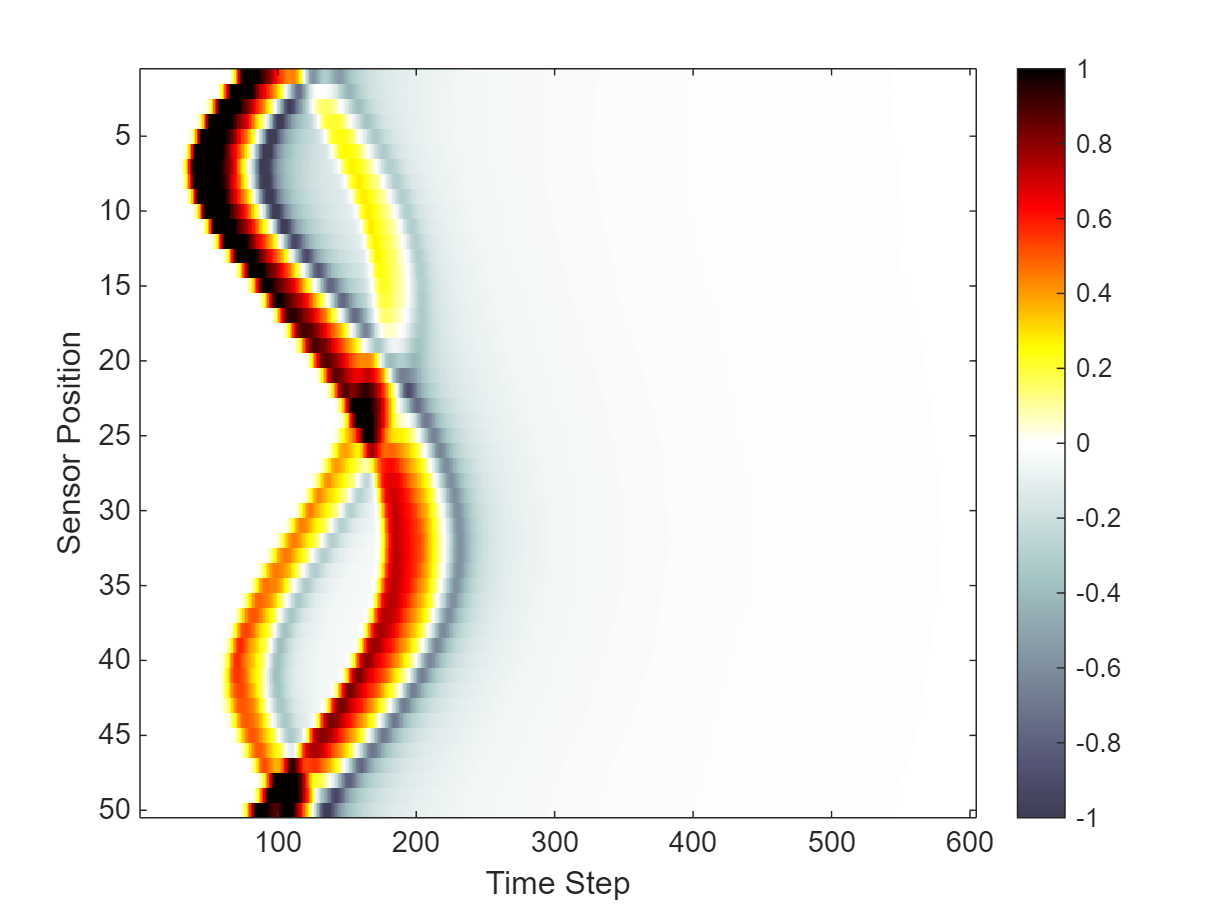

% plot the simulated sensor data
figure;
imagesc(sensor_data, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;

Running k-Wave simulation...
  start time: 14-Oct-2025 17:15:50
  reference sound speed: 1800m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  smoothing p0 distribution...
  calculating Delaunay triangulation...
  precomputation completed in 0.67567s
  starting time loop...
  estimated simulation time 2.8026s...
  simulation completed in 12.152s
  total computation time 12.891s


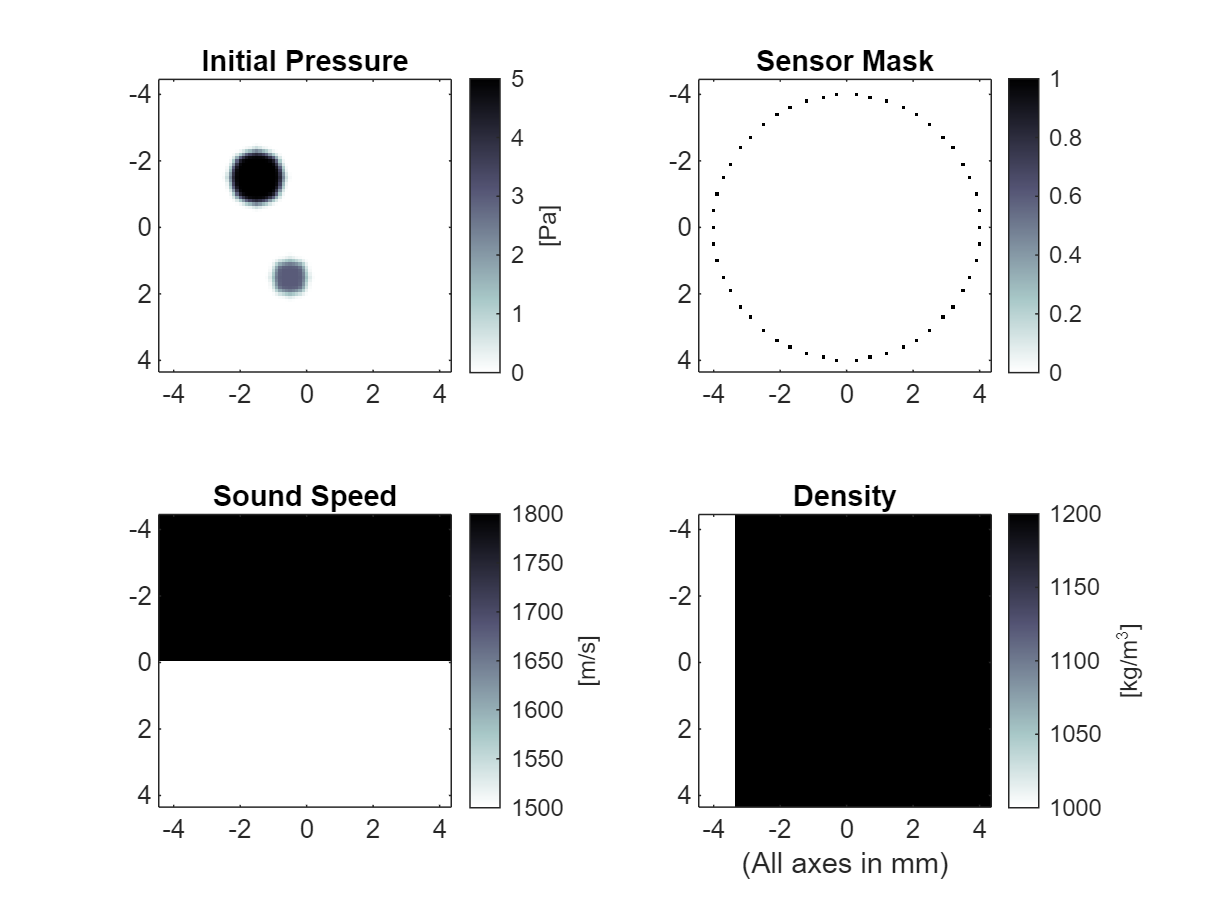

% define the properties of the propagation medium
medium.sound_speed = 1500 * ones(Nx, Ny);   % [m/s]
medium.sound_speed(1:Nx/2, :) = 1800;       % [m/s]
medium.density = 1000 * ones(Nx, Ny);       % [kg/m^3]
medium.density(:, Ny/4:Ny) = 1200;          % [kg/m^3]
% run the simulation with optional inputs for plotting the simulation
% layout in addition to removing the PML from the display
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, ...
    'PlotLayout', true, 'PlotPML', false);

# Recording The Particle Velocity Example

% % create time array
% t_end = 6e-6;       % [s]
% kgrid.makeTime(kgrid,medium.sound_speed,[],t_end);
% define four sensor points centered about source.p0
sensor_radius = 40; % [grid points]
sensor.mask = zeros(Nx, Ny);
sensor.mask(Nx/2 + sensor_radius, Ny/2) = 1;
sensor.mask(Nx/2 - sensor_radius, Ny/2) = 1;
sensor.mask(Nx/2, Ny/2 + sensor_radius) = 1;
sensor.mask(Nx/2, Ny/2 - sensor_radius) = 1;

% set the acoustic variables that are recorded
sensor.record = {'p', 'u'};

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor);

Running k-Wave simulation...
  start time: 14-Oct-2025 17:16:03
  reference sound speed: 1800m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  smoothing p0 distribution...
  precomputation completed in 0.26622s
  starting time loop...
  estimated simulation time 2.259s...
  simulation completed in 11.1509s
  total computation time 11.445s


# Monopole Point Source In A Homogeneous Propagation Medium Example

clear source
% define a single source point
source.p_mask = zeros(Nx, Ny);
source.p_mask(end - Nx/4, Ny/2) = 1;

% define a time varying sinusoidal source
source_freq = 0.25e6;   % [Hz]
source_mag = 2;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * kgrid.t_array);
% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(kgrid, medium, source.p);

Filtering input signal...
  maximum frequency supported by kgrid: 7.5MHz (2 PPW)
  filter cutoff frequency: 5MHz (3 PPW)
  computation complete.


% define the acoustic parameters to record
sensor.record = {'p', 'p_final'};


% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor)

Running k-Wave simulation...
  start time: 14-Oct-2025 17:16:14
  reference sound speed: 1800m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz


  precomputation completed in 0.12147s
  starting time loop...
  estimated simulation time 2.0898s...
  simulation completed in 11.2063s
  total computation time 11.359s


sensor_data = struct with fields:
          p: [4×604 double]
    p_final: [128×128 double]
